## **Brain surface plot with MatLab**

**step 1: Generate "face" and "vertices" of surface using spm**

If you want to plot surface of brain, you should use a segmentation tool (such as FSL) to get the gray 

matter image, and use this image as input to spm_surf. If you want to plot the surface of skull, you can 

input the original structural image but with careful choice of threshold.

spm_surf function go to link[ ](http:// https://github.com/neurodebian/spm12/blob/master/spm_surf)[https://github.com/neurodebian/spm12/blob/master/spm_surf.m](http:// https://github.com/neurodebian/spm12/blob/master/spm_surf.m)

The source code from [https://alivelearn.net/?p=1075](https://alivelearn.net/?p=1075)


SPM8: spm_surf (v4341)                             12:11:39 - 25/11/2019


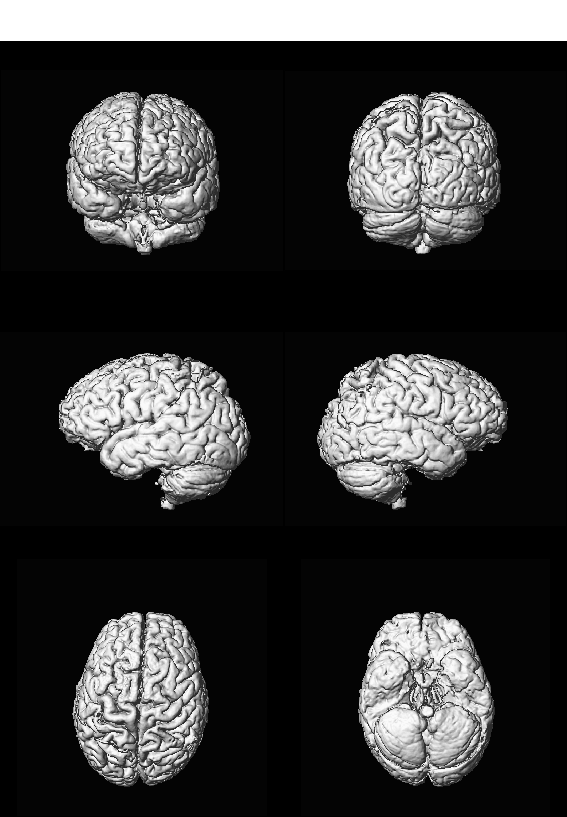



------------------------------------------------------------------------
Running job #1
------------------------------------------------------------------------
Running 'Print'

Printing to
/media/qiang/NEUROEXPLORA_2018/NEUROEXPLORA_2018/Retinotopy-2018/sub-01/func/sub-01_ses-1_task-retinotopy_run-001_bold/spm_processing_stats/spm_2019Nov25.ps
Done    'Print'
Done



gray_matter = ['/media/qiang/NEUROEXPLORA_2018/NEUROEXPLORA_2018/Retinotopy-2018/' ...
                'sub-01/anat/c1sub-01_sT1w.nii'];
%% white matter
spm_surf(gray_matter,3, 0.5);

**Go to add gifti into matlab path, gii format specific for surface format.**

**Go to download gifit toolbox**

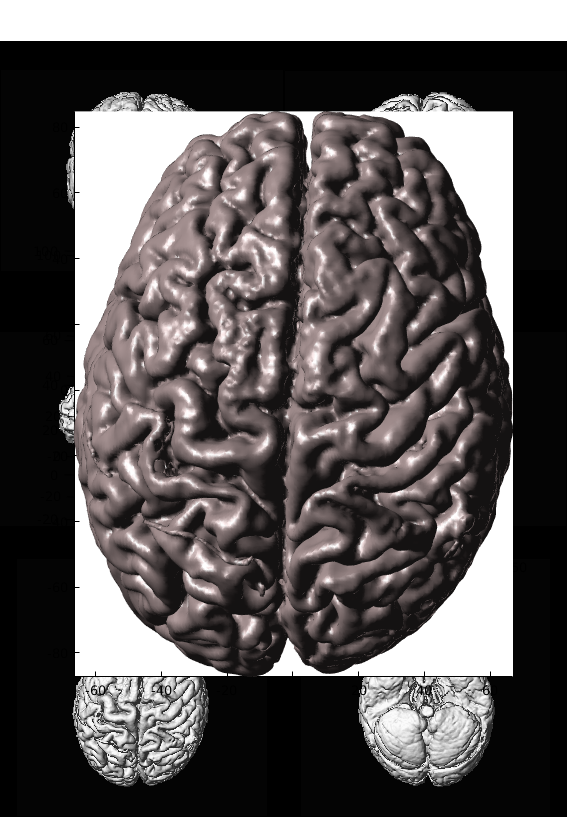

FV = gifti(spm_select(1,'mesh','Select surface data'));
% Display mesh
figure; plot(FV);

FV = export(FV,'patch');
fg = spm_figure('GetWin','Graphics');
ax = axes('Parent',fg);
p  = patch(FV, 'Parent',ax,...
      'FaceColor', [0.8 0.7 0.7], 'FaceVertexCData', [],...
      'EdgeColor', 'none',...
      'FaceLighting', 'phong',...
      'SpecularStrength' ,0.7, 'AmbientStrength', 0.1,...
      'DiffuseStrength', 0.7, 'SpecularExponent', 10);
set(0,'CurrentFigure',fg);
set(fg,'CurrentAxes',ax);
l  = camlight(-40, 20); 
axis image;
rotate3d on;

**Display the activation areas in the brain surface, here is a example: **[**surf**](https://gllmflndn.github.io/gifti/)

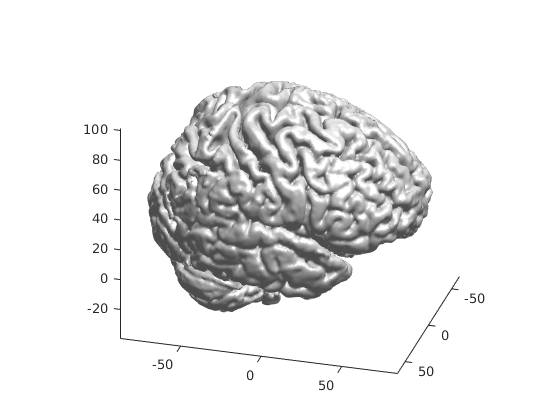

%FV = gifti(spm_select(1,'mesh','Select surface data'));
F = patch('faces',FV.faces,'vertices',FV.vertices,'facecolor','flat','edgecolor', ...
        'none', 'facealpha', 1);
facecolor = repmat([1 1 1], length(FV.faces), 1);
set(F,'FaceVertexCData',facecolor);

daspect([1 1 1])
view(3); axis tight
view([50 -40 100])
camlight
lighting gouraud 

view([26 67])

**Step 3. Overlay a functional image**

**The strategy here is that you first get the coordinates of the activated voxels and the corresponding colors you want to use for each voxel  (presumablly dependent on the intensity of each voxel). Then find the  vertices and faces that are “close” to the coordinates, and change the  face color.**

% get the coordnite
v = spm_vol(spm_select(1,'image','Select Statis data')); % functional image file
m = spm_read_vols(v);
disp(m)


(:,:,1) =

  Columns 1 through 16

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

threshold = 0;
pos = find(m>=threshold);


[xyzcor(:,1) xyzcor(:,2) xyzcor(:,3)] = ind2sub(size(m), pos);
addpath /home/qiang/QiangLi/Matlab_Utils_Functional/;
xyz = cor2mni(xyzcor, v.mat);
intensity = m(pos);

% convet intensity into color
tmp = hot; % using 'hot' color scheme
mx = max(intensity);
mn = min(intensity);
intensity = round((intensity-mn)/(mx-mn) * 63 + 1);
colors = tmp(intensity,:);

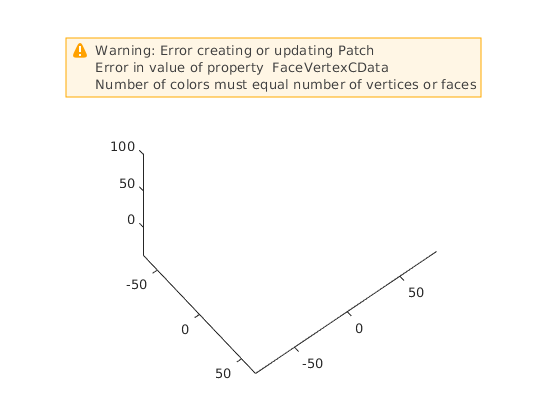


% Plot
distanceThreshold = 2;
F = patch('faces',FV.faces,'vertices',FV.vertices,'facecolor','flat','edgecolor', ...
    'none', 'facealpha', 1);
facecolor = repmat([1 1 1], length(FV.faces), 1);
pos = [];
for ii=1:size(xyz, 1)
tmp = find(abs(FV.vertices(:,1)-xyz(ii, 1)) <= distanceThreshold & ...
      abs(FV.vertices(:,2)-xyz(ii, 2)) <= distanceThreshold & abs(FV.vertices(:,3)-xyz(ii, 3)) ...
      <= distanceThreshold);
pos = [tmp];
posf = find(sum(ismember(FV.faces, pos),2)>0);
facecolor(posf,:) = repmat(colors(ii,:), length(posf), 1);
end

set(p,'FaceVertexCData',facecolor);

daspect([1 1 1])
view(3); axis tight
view([50 -40 100])
camlight
lighting gouraud

**The activation brain surface map for task MRI**

**Interesting: why only half of brain response the corresponding stimuli?**